clear x
syms x
int(2/sqrt(sym(pi)) * exp(-x^2))

$$ans = \mathrm{erf}\left(x\right)$$

syms z real
simplify(int(exp(-z^2),[s,Inf]))

$$ans = -\frac{\sqrt{\pi }\,\left(\mathrm{erf}\left(s\right)-1\right)}{2}$$

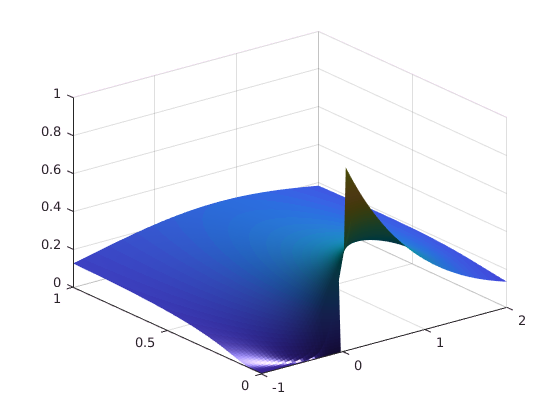

[t,x] = meshgrid(linspace(0,0.1,100),linspace(-1,2,100));
k = 1;
u = exp(k*t - x) .* (1 - normcdf( (2*k*t - x) ./ sqrt(2*k*t) ) );
surf(x,t,u), shading interp; light